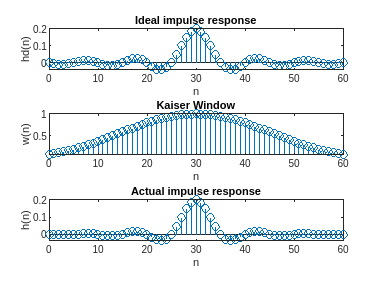

clear;close;clc;
%wp=input('enter wp');
wp=0.2*pi; wc=wp;
ws=0.3*pi;
As=50;
Rp=0.25;
tr_width=ws-wp;
N=ceil((As-7.95)/(2.285*tr_width)+1)+1;
n=0:1:N-1;
beta=0.1102*(As-8.7);
fc=wc/pi;
alpha=(N-1)/2;
m=n-alpha;
hd=sin(wc*(n-alpha))./(pi*(n-alpha));%ideal impulse response
hd(alpha+1)=wc/pi;
w_kaiser=(kaiser(N,beta))'; % take transpose for multiplication
h=hd.*w_kaiser;
subplot(311),stem(n,hd),title('Ideal impulse response');
xlabel('n'),ylabel('hd(n)');
subplot(312),stem(n,w_kaiser),title('Kaiser Window');
xlabel('n'),ylabel('w(n)');
subplot(313),stem(n,h),title('Actual impulse response');
xlabel('n'),ylabel('h(n)');

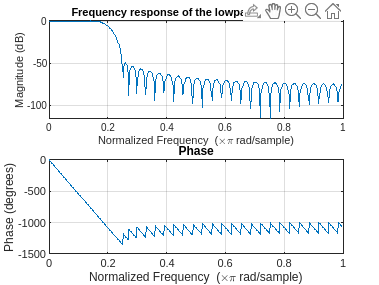

figure;
freqz(h,1);%1 is the normalized frequency
title('Frequency response of the lowpass digital filter');